# 2.1

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

# 2.2

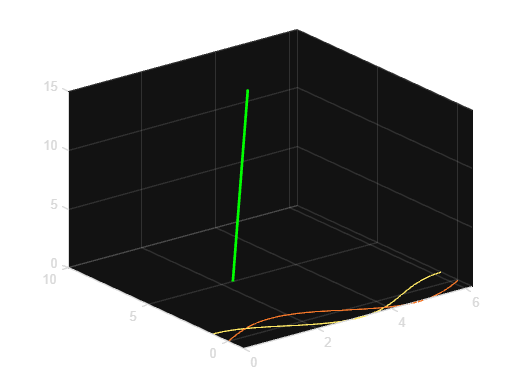

x=0:0.1:2*pi;
grid on;
hold on;
plot(x, sin(x))
plot(x, cos(x))
hold off

# 2.3

y=log(1:2:9)

y =          0    1.0986    1.6094    1.9459    2.1972


y(1)

ans = 0

# 2.4

a=(-10:2:20)

a =    -10    -8    -6    -4    -2     0     2     4     6     8    10    12    14    16    18    20


b=(10:-2:0)

b =     10     8     6     4     2     0


# 2.5

[1 2 3]*2

ans =      2     4     6


[2 -1 9]+[1 3 6]

ans =      3     2    15


[2 5 7] + 3

ans =      5     8    10



a = 1:2:10

a =      1     3     5     7     9


b = 1:5

b =      1     2     3     4     5


a .* b

ans =      1     6    15    28    45


a ./ b

ans =     1.0000    1.5000    1.6667    1.7500    1.8000


a .^ 2

ans =      1     9    25    49    81


a'

ans =      1
     3
     5
     7
     9


# 2.6

a = [1 4 6];
b = [-1 2 1];

a+b

ans =      0     6     7


a*2

ans =      2     8    12


a/2

ans =     0.5000    2.0000    3.0000


a+3

ans =      4     7     9


a*b' % error ohne '

ans = 13

a.*b

ans =     -1     8     6


a./b

ans =     -1     2     6


# 2.7

A = eye(3,3);
B = [1 2 3; 4 5 6; 7 8 9];
A+B

ans =      2     2     3
     4     6     6
     7     8    10


A*2

ans =      2     0     0
     0     2     0
     0     0     2


A/2

ans =     0.5000         0         0
         0    0.5000         0
         0         0    0.5000


B.^2

ans =      1     4     9
    16    25    36
    49    64    81


A.*B

ans =      1     0     0
     0     5     0
     0     0     9


A*B

ans =      1     2     3
     4     5     6
     7     8     9


# 2.8

points =      1     2     3
     4     8    13


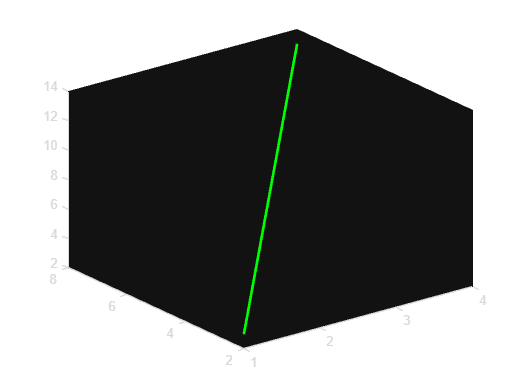

vec1 = [1 2 3];
vec2 = [4 8 13];

myLine(vec1, vec2, "g", 2);

function myLine(Vec1, Vec2, color, width)
    %xs = [Vec1(1) Vec2(1)]
    %ys = [Vec1(2) Vec2(2)]
    %zs = [Vec1(3) Vec2(3)]

    points = [Vec1; Vec2];
    plot3(points(:,1), points(:,2), points(:,3), "Color", color, "LineWidth", width)
end